 Section-1 

%By Kunal Kishore ,16093
% m = inital number of steps ,i.e degree of precision
% from where calculation should start
m=4;

% k ,largest value of steps,i.e  degree of precision =
% till which to calculate
k=2048;

%[a,b] is the interval over which function to be intregated
a=0;
b=1;
n=m;
i = 1 ;
N = ones(10,1);

while (n <= k)
    N(i) =n;
    
    n = n*2;
    i = i+1;
end


%function to be intregated
syms f(z)
f(z) =  (z -z*log(z))^0.5

$$f(z) = \sqrt{z-z\,\log\left(z\right)}$$


I_real = double(int(f(z),[a,b]));

 Trapeziodal Rule Calculation

%For calculating Trapeziodal Rule
n=m;
i = 1 ;
area_by_T = ones(10,1);
while (n <= k)
    area_by_T(i) = mytrapeziod(f,n,a,b);
    n = n*2;
    i = i+1;
end
format longG

errorT =abs(area_by_T -ones(10,1)*I_real) ;
disp("Trapeziodal Rule")

Trapeziodal Rule


disp(table(N , area_by_T , errorT))

     N          area_by_T               errorT       
    ____    _________________    ____________________

       4    0.572254224932866       0.274427875110903
       8    0.725214200324718       0.121467899719051
      16    0.792625912534477      0.0540561875092919
      32    0.822357855823603      0.0243242442201663
      64    0.835584709899151      0.0110973901446186
     128    0.841544988126031     0.00513711191773825
     256    0.844270564862936     0.00241153518083315
     512    0.845535650826942     0.00114644921682761
    1024    0.846131114590108    0.000550985453661612
    2048     0.84641489469237    0.000267205351399791



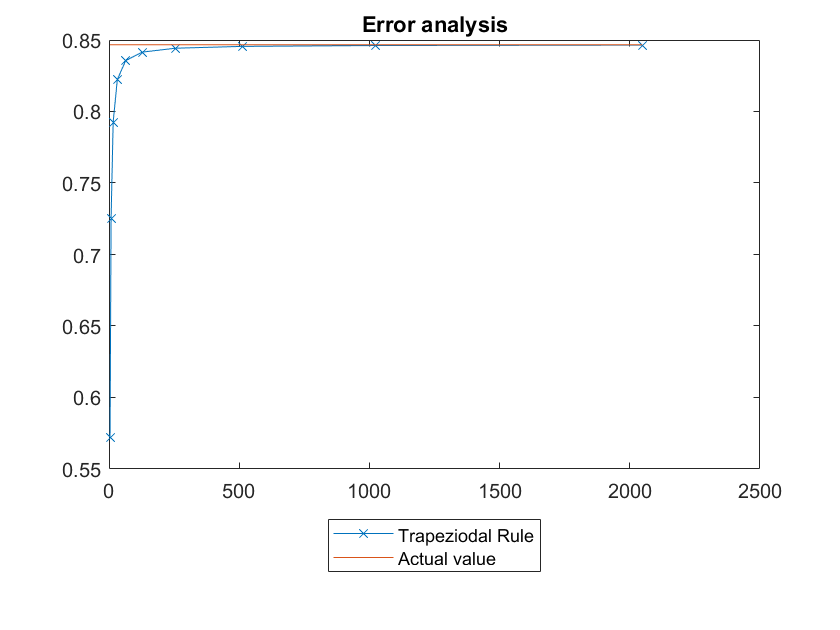


plot(N , area_by_T,'-x')
hold on
plot(N ,I_real*ones(10,1))
hold off
title("Error analysis")
x123 = legend("Trapeziodal Rule","Actual value");
x123.Location ='southoutside';

Simpson Rule Calculation

%For calculating Simpson 1/3 Rule 
n = m ;
i = 1 ;
area_by_S= ones(10,1) ;
while (n <= k)
    
    h = (b-a)/n;
    curr = 0 + f(b);
    for q = 1:2:n-1   %n is even
        curr = curr + 4*f(a + q*h);
        
    end
    for q = 2:2:n-2 
        curr = curr +2*f(a + q*h);
    end
    
    area_by_S(i) = 1/3 *h *curr;
    i=i+1;
    n = n*2;
    
end

disp("Simpson 1/3 Rule ")

Simpson 1/3 Rule 



errorS =abs(area_by_S -ones(10,1)*I_real);
disp(table(N , area_by_S , errorS))

     N          area_by_S               errorS       
    ____    _________________    ____________________

       4    0.821720204391985      0.0249618956517842
       8    0.837387237549854     0.00929486249391565
      16    0.843236696234862     0.00344540380890701
      32    0.845409757520094     0.00127234252367581
      64    0.846213764216692    0.000468335827077615
     128    0.846510198804341    0.000171901239427896
     256    0.846619161169818    6.29388739515901e-05
     512    0.846659106596401    2.29934473680027e-05
    1024     0.84667371622527    8.38381849976866e-06
    2048    0.846679048470915    3.05157285440671e-06



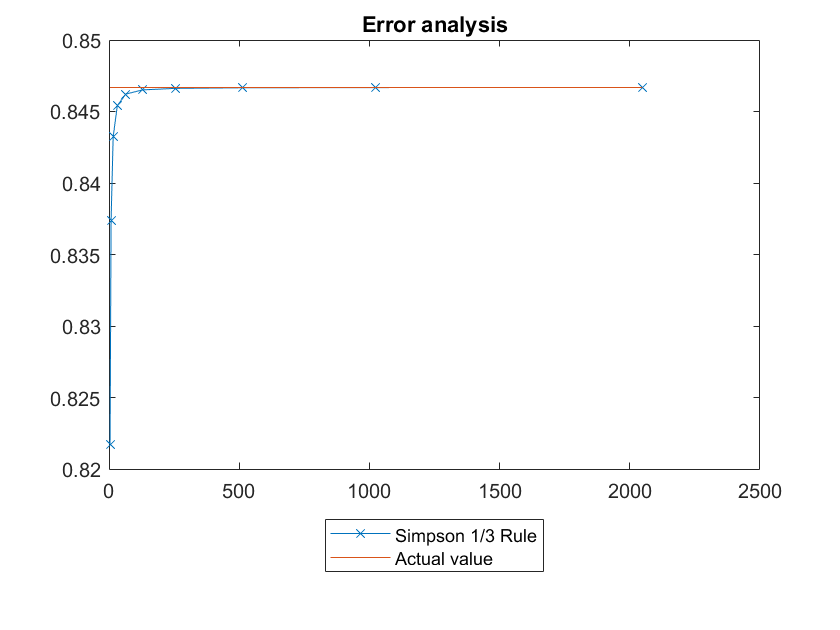


plot(N , area_by_S,'-x')
hold on
plot(N ,I_real*ones(10,1))
hold off
title("Error analysis")
x123=legend("Simpson 1/3 Rule","Actual value");
x123.Location ='southoutside'	;

Gaussian quadrature calculation

%For calculating Gauss–Legendre quadrature

n = m ;
i = 1 ;
area_by_G = ones(10,1);

while (n <= k )
    h=(b-a)/n;
    
    [xi,wi] = lgwt(n,a,b) ; 
    curr = 0;
    z = 1;
    while  (z <= n) 
        curr = curr + wi(z)*f(xi(z));
        z=z+1;    
    end
    area_by_G(i) = curr;
    
    i = i+1;
    n = n*2 ;
 
end

disp("Gauss–Legendre quadrature ")

Gauss–Legendre quadrature 



errorG =abs(area_by_G -ones(10,1)*I_real) ;
disp(table(N , area_by_G,errorG))

     N          area_by_G               errorG       
    ____    _________________    ____________________

       4    0.849340371516668     0.00265827147289832
       8    0.847111511460532    0.000429411416763115
      16    0.846745989120161    6.38890763919875e-05
      32    0.846691129882344    9.02983857442585e-06
      64    0.846683337266913    1.23722314326891e-06
     128    0.846682266373365     1.6632959543017e-07
     256    0.846682122136145    2.20923755955837e-08
     512    0.846682102954358    2.91058843693293e-09
    1024    0.846682100425001    3.81231601842558e-10
    2048    0.846682100093483    4.97137886412702e-11



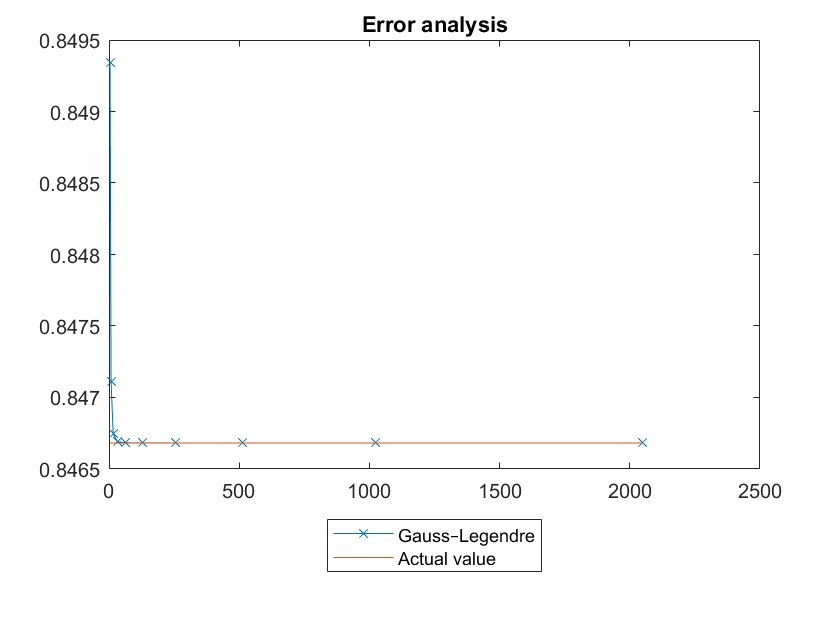


plot(N , area_by_G,'-x')
hold on
plot(N ,I_real*ones(10,1))
hold off
title("Error analysis")
x123=legend("Gauss–Legendre","Actual value");
x123.Location ='southoutside'	;

Displaying the result

fprintf("Actual value of integration:'%f%+fi\n", real(I_real), imag(I_real))

Actual value of integration:'0.846682+0.000000i


disp(table(N,area_by_T , area_by_S , area_by_G))

     N          area_by_T            area_by_S            area_by_G    
    ____    _________________    _________________    _________________

       4    0.572254224932866    0.821720204391985    0.849340371516668
       8    0.725214200324718    0.837387237549854    0.847111511460532
      16    0.792625912534477    0.843236696234862    0.846745989120161
      32    0.822357855823603    0.845409757520094    0.846691129882344
      64    0.835584709899151    0.846213764216692    0.846683337266913
     128    0.841544988126031    0.846510198804341    0.846682266373365
     256    0.844270564862936    0.846619161169818    0.846682122136145
     512    0.845535650826942    0.846659106596401    0.846682102954358
    1024    0.846131114590108     0.84667371622527    0.846682100425001
    2048     0.84641489469237    0.846679048470915    0.846682100093483

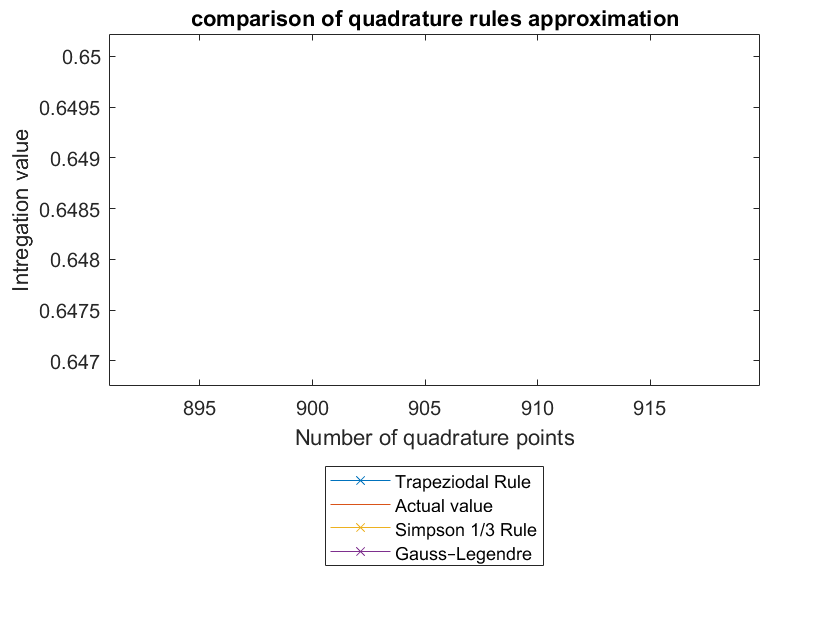


plot(N,area_by_T,'-x')
xlabel("Number of quadrature points")
ylabel("Intregation value")
hold on
plot(N ,I_real*ones(10,1))
plot(N,area_by_S,'-x')
plot(N,area_by_G,'-x')
hold off
title("comparison of quadrature rules approximation")
x123=legend("Trapeziodal Rule ","Actual value","Simpson 1/3 Rule " ...
   ,"Gauss–Legendre ");
x123.Location ='southoutside';

disp("Error comparison")

Error comparison


disp(table(N,errorT , errorS , errorG))

     N             errorT                  errorS                  errorG       
    ____    ____________________    ____________________    ____________________

       4       0.274427875110903      0.0249618956517842     0.00265827147289832
       8       0.121467899719051     0.00929486249391565    0.000429411416763115
      16      0.0540561875092919     0.00344540380890701    6.38890763919875e-05
      32      0.0243242442201663     0.00127234252367581    9.02983857442585e-06
      64      0.0110973901446186    0.000468335827077615    1.23722314326891e-06
     128     0.00513711191773825    0.000171901239427896     1.6632959543017e-07
     256     0.00241153518083315    6.29388739515901e-05    2.20923755955837e-08
     512     0.00114644921682761    2.29934473680027e-05    2.91058843693293e-09
    1024    0.000550985453661612    8.38381849976866e

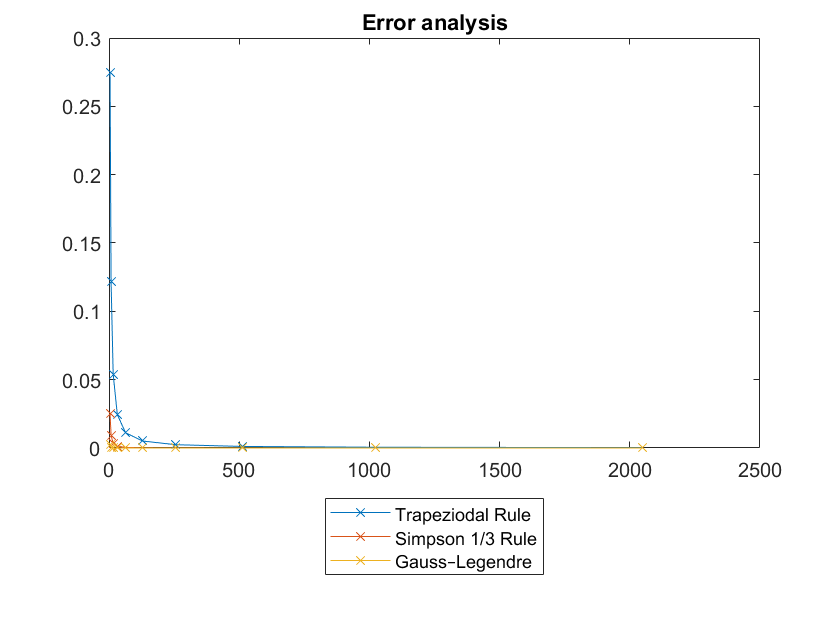


plot(N ,errorT,'-x')
hold on
plot(N,errorS,'-x')
plot(N,errorG,'-x')
hold off
x123=legend("Trapeziodal Rule ","Simpson 1/3 Rule " ...
   ,"Gauss–Legendre ");
x123.Location ='southoutside'	;
title("Error analysis")

Function Definition

function [x,w]=lgwt(N,a,b)

N=N-1;
N1=N+1; N2=N+2;
xu=linspace(-1,1,N1)';
% Initial guess
y=cos((2*(0:N)'+1)*pi/(2*N+2))+(0.27/N1)*sin(pi*xu*N/N2);
% Legendre-Gauss Vandermonde Matrix
L=zeros(N1,N2);
% Derivative of LGVM
Lp=zeros(N1,N2);
% Compute the zeros of the N+1 Legendre Polynomial
% using the recursion relation and the Newton-Raphson method
y0=2; 
% Iterate until new points are uniformly within epsilon of old points
while max(abs(y-y0))>eps
    
    
    L(:,1)=1;
    Lp(:,1)=0;
    
    L(:,2)=y;
    Lp(:,2)=1;
    
    for k=2:N1
        L(:,k+1)=( (2*k-1)*y.*L(:,k)-(k-1)*L(:,k-1) )/k;
    end
 
    Lp=(N2)*( L(:,N1)-y.*L(:,N2) )./(1-y.^2);   
    
    y0=y;
    y=y0-L(:,N2)./Lp;
    
end
% Linear map from[-1,1] to [a,b]
x=(a*(1-y)+b*(1+y))/2;      
%Compute the weights
w=(b-a)./((1-y.^2).*Lp.^2)*(N2/N1)^2;
end


function I = mytrapeziod(f,N,A,B)
        dx =(B-A)/N;
        I=0;
        for x = (A+dx):dx:(B-dx)
            if (x + dx) < 1
                I = I + 0.5*(f(x) +f(x+dx))*dx ;
            elseif (x + dx) == 1
                I = I + 0.5*(f(x) +0 )*dx ;
            end
        end
end